Homework 1

a

f = @(x) cos(x);
fprime = @(x) -sin(x); % derivative of cos(x)

x = 0.25;
h = 0.01; 

faprx = (f(x + h) - f(x)) / h; % [cos(x+h)-cos(x)]/h

AD = abs(fprime(x) - faprx); % |-sin(x) - [cos(x+h)-cos(x)]/h| where x = 0.25

b c

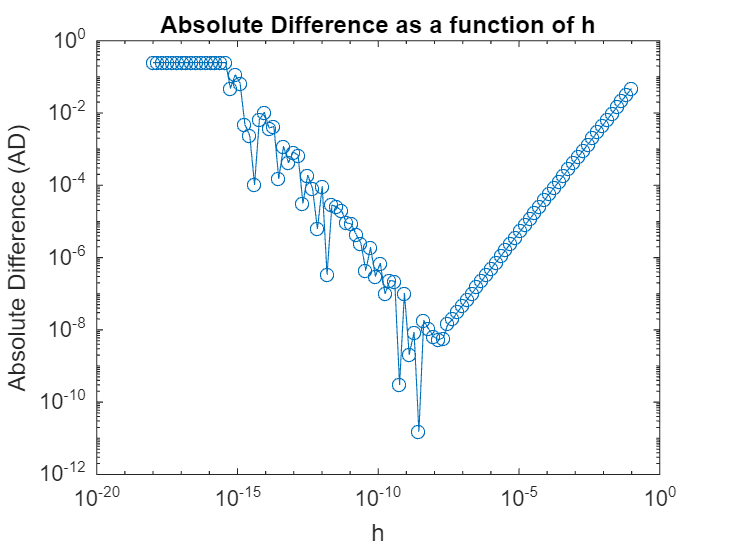

% Absolute Difference
f = @(x) cos(x);
fprime = @(x) -sin(x);

x = 0.25;
h_val = logspace(-18, -1, 100);

AD_val = size(h_val);

for i = 1:length(h_val)
    h = h_val(i);
    faprx = (f(x + h) - f(x)) / h;
    AD_val(i) = abs(fprime(x) - faprx);
end

loglog(h_val, AD_val, 'o-');
title('Absolute Difference as a function of h');
xlabel('h');
ylabel('Absolute Difference (AD)');

d

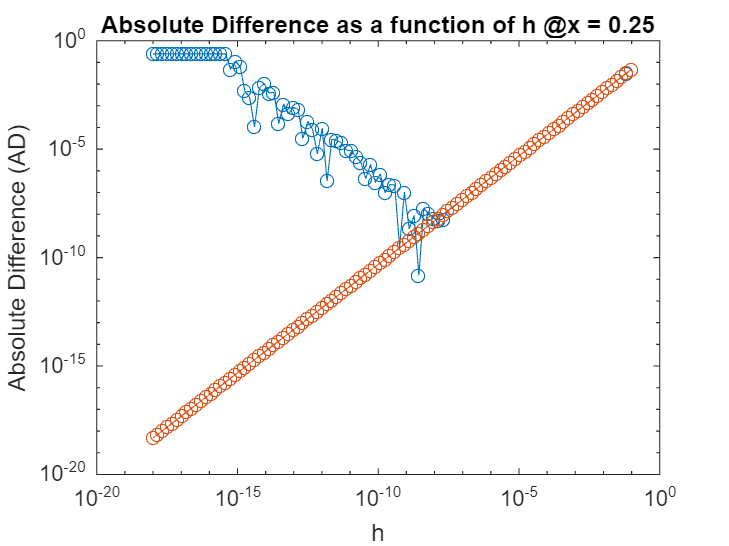

% Absolute Difference and EA
f = @(x) cos(x);
fprime = @(x) -sin(x);
f2prime = @(x) -cos(x);

x = 0.25;
h_val = logspace(-18, -1, 100);

AD_val = size(h_val);
EA_val = size(h_val);

for i = 1:length(h_val)
    h = h_val(i);
    faprx = (f(x + h) - f(x)) / h;
    AD_val(i) = abs(fprime(x) - faprx);
    EA_val(i) = h * abs(f2prime(x)) / 2;
end

loglog(h_val, AD_val, 'o-'); %blue
hold on
loglog(h_val, EA_val, 'o-'); %orange
title('Absolute Difference as a function of h @x = 0.25');
xlabel('h');
ylabel('Absolute Difference (AD)');
hold off

e

Yes, the portion of the graph where the EA agrees with or is larger than the AD is from around (1.45083e-07,7.02863e-08) to around (0.1, 0.0484456), which is the last half of the graph around e-09.

f

Yes, the portion of the graph where the EA is smaller than the AD is from to around (1e-18, 0.247404) to around (1.8782e-09, 8.61737e-09), which is the first half of the graph around e-09.

g When h is relatively large, truncation error dominates, and AD tends to be larger than EA. But as h decreases, truncation error diminishes, and round-off error becomes more prominent. At some point near the , round-off error starts to dominate, causing AD to deviate from EA. 

h

x=0.1

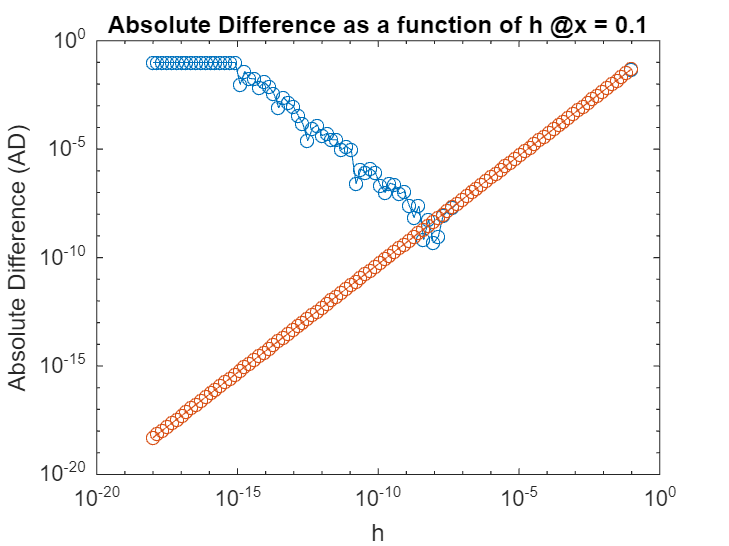

% Absolute Difference and EA
f = @(x) cos(x);
fprime = @(x) -sin(x);
f2prime = @(x) -cos(x);

x = 0.1;
h_val = logspace(-18, -1, 100);

AD_val = size(h_val);
EA_val = size(h_val);

for i = 1:length(h_val)
    h = h_val(i);
    faprx = (f(x + h) - f(x)) / h;
    AD_val(i) = abs(fprime(x) - faprx);
    EA_val(i) = h * abs(f2prime(x)) / 2;
end

loglog(h_val, AD_val, 'o-'); %blue
hold on
loglog(h_val, EA_val, 'o-'); %orange
title('Absolute Difference as a function of h @x = 0.1');
xlabel('h');
ylabel('Absolute Difference (AD)');
hold off

x = pi/3

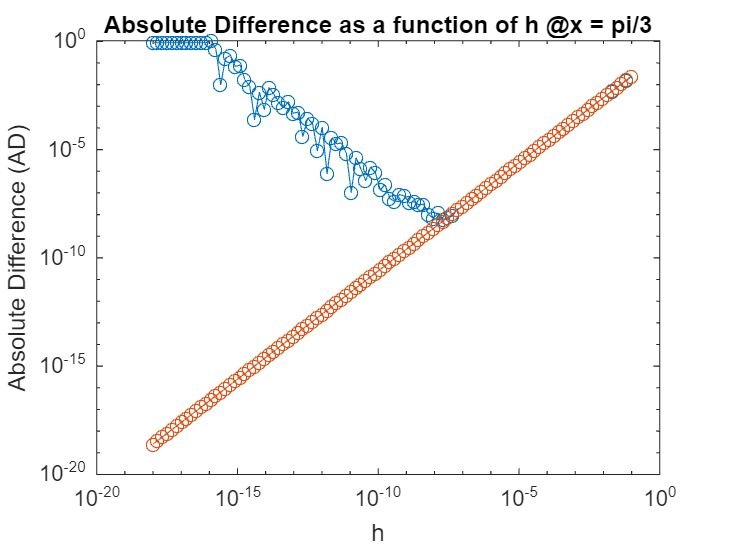

% Absolute Difference and EA
f = @(x) cos(x);
fprime = @(x) -sin(x);
f2prime = @(x) -cos(x);

x = pi/3;
h_val = logspace(-18, -1, 100);

AD_val = size(h_val);
EA_val = size(h_val);

for i = 1:length(h_val)
    h = h_val(i);
    faprx = (f(x + h) - f(x)) / h;
    AD_val(i) = abs(fprime(x) - faprx);
    EA_val(i) = h * abs(f2prime(x)) / 2;
end

loglog(h_val, AD_val, 'o-'); %blue
hold on
loglog(h_val, EA_val, 'o-'); %orange
title('Absolute Difference as a function of h @x = pi/3');
xlabel('h');
ylabel('Absolute Difference (AD)');
hold off

In comparison, the results of error still occurs around e-09 and the graphs generally look similar. However, each pair of EA and AD graphs differ because the curvature of the cosine and sine curves, the rate of change of the functions, and the first and second derivatives will influence the error characteristics for each x value. For pi/3, the ED goes over AD over a smaller range than the 0.1 and 0.25 near e-09. 